# 01 | Continuous LFP preprocessing

PURPOSE: inspect a continuous signal, remove drift, filter, resample and save. INPUT: optional MAT with one vector named data/data1 and scalar fs (Hz). OUTPUT: _example_outputs/01_preprocess/preprocessed_example.mat + QC figure. TOOLBOXES: Signal Processing; Optimization (only for adaptive notch). Run this file section by section. All editable settings are in section 1. The default is a controlled SYNTHETIC demonstration with a known reference. Do not run this preprocessing again on the already processed release segments.

## 1. Paths and settings / 路径与参数

codeDir = fileparts(mfilename('fullpath'));
if ~isempty(getenv('GATE_OFFLINE_CODE_DIR'))
    codeDir = getenv('GATE_OFFLINE_CODE_DIR');
end
addpath(fullfile(codeDir,'functions'));
outDir = gate_output_dir(codeDir,'01_preprocess');

inputFile = '';                   % Empty = synthetic demonstration.
targetFs = 300;                   % Archived offline segment rate, Hz.
lowPassHz = 90; lowStopHz = 95;
highPassHz = 2; highStopHz = 1;
passRippleDb = 0.01; stopAttenDb = 30;
applyNotch = true;                % Set according to recording/QC, not outcome.
notchHz = 50;                     % Power-line interference, NOT stimulation.
notchWidthHz = 2; referenceWidthHz = 6;
previewSeconds = [10 15];

## 2. Load one continuous record 

Replace inputFile to use a real exported recording. This example does not bundle the acquisition-system reader or assume a channel's amplitude unit.

if isempty(inputFile)
    rng(23,'twister'); fs = 1000;
    timeRaw = (0:120*fs-1)'/fs;
    slowActivity = sin(2*pi*8*timeRaw);
    gammaEnvelope = 0.3 + 0.5*(sin(2*pi*0.45*timeRaw)>0.7);
    cleanReference = slowActivity + gammaEnvelope.*sin(2*pi*60*timeRaw) ...
        + 0.15*randn(size(timeRaw));
    baselineDrift = 1.5*sin(2*pi*0.25*timeRaw) + 0.005*timeRaw;
    lineNoise = 0.8*sin(2*pi*50*timeRaw);
    raw = cleanReference + baselineDrift + lineNoise;
    sourceLabel = 'SYNTHETIC signal: known reference plus drift and 50-Hz noise';
else
    [raw,fs] = gate_load_lfp(inputFile);
    timeRaw = (0:numel(raw)-1)'/fs;
    cleanReference = [];          % Unknown for an actual recording.
    sourceLabel = 'User-supplied continuous recording';
end
inputFs = fs;
assert(inputFs>2*lowStopHz && targetFs>2*lowStopHz,'Check sample rates.');

## 3. Remove linear trend

This does not remove all slow drift; the high-pass stage below removes activity below the analysis passband. Offline filtfilt is noncausal.

detrended = detrend(raw,1);

## 4. Low-pass before downsampling 

Same Chebyshev-I specifications as the original preprocessing workflow. Second-order sections avoid polynomial coefficient instability. Explicit reflection padding lets filter-edge transients settle outside the record.

[filterOrder,cutoff] = cheb1ord(lowPassHz/(inputFs/2), ...
    lowStopHz/(inputFs/2),passRippleDb,stopAttenDb);
[z,p,k] = cheby1(filterOrder,passRippleDb,cutoff,'low');
[sos,gain] = zp2sos(z,p,k);
[lowPassed,lowPadSamples] = gate_zero_phase(sos,gain,detrended);

## 5. Resample and high-pass 

resample includes its own anti-alias filter; fs must follow the output data.

[upFactor,downFactor] = rat(targetFs/inputFs,1e-12);
resampled = resample(lowPassed,upFactor,downFactor);
fs = targetFs;
[filterOrder,cutoff] = cheb1ord(highPassHz/(fs/2), ...
    highStopHz/(fs/2),passRippleDb,stopAttenDb);
[z,p,k] = cheby1(filterOrder,passRippleDb,cutoff,'high');
[sos,gain] = zp2sos(z,p,k);
[bandPassed,highPadSamples] = gate_zero_phase(sos,gain,resampled);

## 6. Optional adaptive line-noise notch

The original helper adapts the stopband attenuation against neighboring PSD. These filters do not replace stimulation-artifact removal in the online Qt system. Stimulation-phase spectra still require inspection for residual peaks.

data = bandPassed;
if applyNotch
    data = spAdaptiveNotchFilter(data,fs,notchWidthHz,referenceWidthHz,notchHz);
end
data = data(:);
assert(all(isfinite(data)),'Filtering returned nonfinite samples.');

## 7. Inspect time-domain and spectral changes

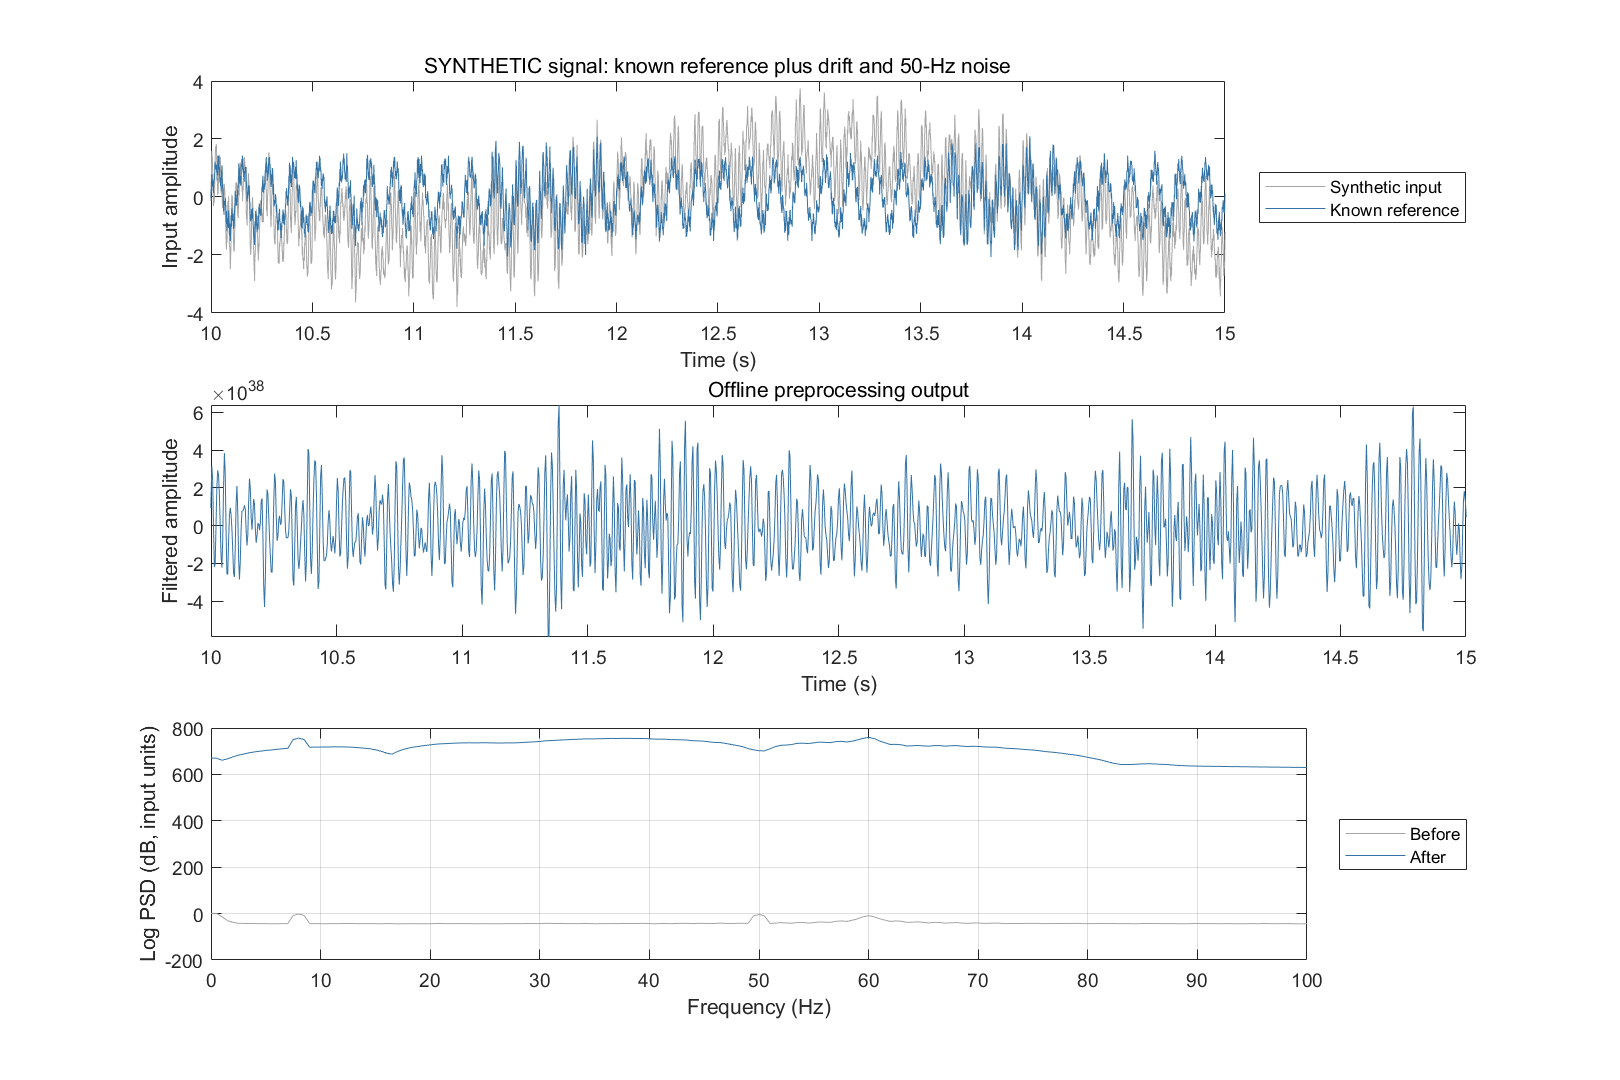

fig = figure('Color','w','Position',[100 100 1080 720]);
subplot(3,1,1);
plot(timeRaw,raw,'Color',[0.65 0.65 0.65]); hold on;
if ~isempty(cleanReference)
    plot(timeRaw,cleanReference,'Color',[0.2 0.45 0.65]);
    legend('Synthetic input','Known reference','Location','eastoutside');
end
xlim(previewSeconds); xlabel('Time (s)'); ylabel('Input amplitude');
title(sourceLabel,'Interpreter','none');
subplot(3,1,2);
plot((0:numel(data)-1)/fs,data,'Color',[0.2 0.45 0.65]);
xlim(previewSeconds); xlabel('Time (s)'); ylabel('Filtered amplitude');
title('Offline preprocessing output');
subplot(3,1,3);
[pBefore,fBefore] = pwelch(raw,gate_hann(round(2*inputFs),'periodic'), ...
    round(inputFs),round(2*inputFs),inputFs);
[pAfter,fAfter] = pwelch(data,gate_hann(round(2*fs),'periodic'),round(fs),round(2*fs),fs);
plot(fBefore,10*log10(max(pBefore,realmin)),'Color',[0.65 0.65 0.65]); hold on;
plot(fAfter,10*log10(max(pAfter,realmin)),'Color',[0.2 0.45 0.65]);
xlim([0 100]); xlabel('Frequency (Hz)'); ylabel('Log PSD (dB, input units)');
legend('Before','After','Location','eastoutside'); grid on;

## 8. Save data and settings 

Inputs are never overwritten. Re-running replaces only generated outputs.

settings = struct('input_fs',inputFs,'output_fs',fs,'low_pass_hz',lowPassHz, ...
    'high_pass_hz',highPassHz,'notch_enabled',applyNotch,'notch_hz',notchHz, ...
    'pass_ripple_db',passRippleDb,'stop_attenuation_db',stopAttenDb, ...
    'lowpass_reflection_samples',lowPadSamples,'highpass_reflection_samples',highPadSamples);
save(fullfile(outDir,'preprocessed_example.mat'),'data','fs','sourceLabel','settings');
exportgraphics(fig,fullfile(outDir,'preprocessing_QC.png'),'Resolution',180);

fprintf('Saved %.1f s at %.0f Hz. Next: step02_segment_and_inspect.\n',numel(data)/fs,fs);

Saved 120.0 s at 300 Hz. Next: step02_segment_and_inspect.
